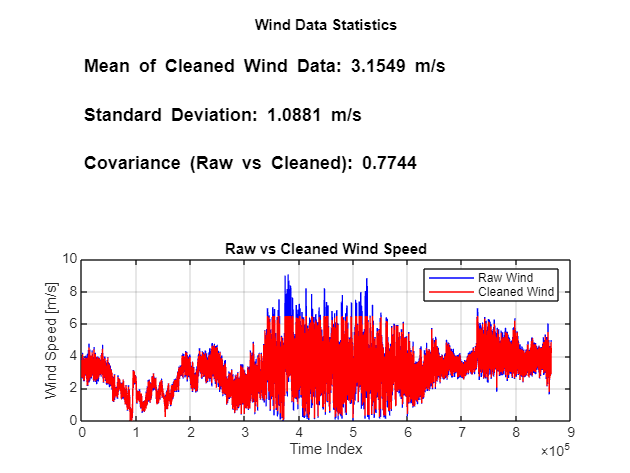

clear; close all;

%% === Step 1: Load and Clean Wind Data ===
A = importdata('31Oct2024.dat');
wind_speed = A.data(:,1);  % Assuming wind speed in column 1

% Remove NaNs and non-physical values
valid_idx = ~isnan(wind_speed) & wind_speed > 0;
wind_clean = wind_speed(valid_idx);

% Despike using median filter
wind_despiked = medfilt1(wind_clean, 5);

% Remove ±3σ outliers
mean_wind = mean(wind_despiked);
std_wind = std(wind_despiked);
upper_limit = mean_wind + 3 * std_wind;
lower_limit = mean_wind - 3 * std_wind;
wind_final = wind_despiked(wind_despiked >= lower_limit & wind_despiked <= upper_limit);

%% === Step 2: Compute Statistics ===
mean_clean = mean(wind_final);
std_clean = std(wind_final);
cov_rw_cw = cov(wind_clean(1:length(wind_final)), wind_final);
cov_value = cov_rw_cw(1,2);

%% === Step 3: Plot Raw vs Cleaned and Statistics ===
figure;
subplot(2,1,1);
axis off;
text(0, 0.8, sprintf('\\bfMean of Cleaned Wind Data: %.4f m/s', mean_clean), 'FontSize', 12);
text(0, 0.5, sprintf('\\bfStandard Deviation: %.4f m/s', std_clean), 'FontSize', 12);
text(0, 0.2, sprintf('\\bfCovariance (Raw vs Cleaned): %.4f', cov_value), 'FontSize', 12);
title('Wind Data Statistics');

subplot(2,1,2);
plot(wind_clean, 'b'); hold on;
plot(find(wind_despiked >= lower_limit & wind_despiked <= upper_limit), wind_final, 'r');
grid on;
xlabel('Time Index');
ylabel('Wind Speed [m/s]');
legend('Raw Wind', 'Cleaned Wind');
title('Raw vs Cleaned Wind Speed');

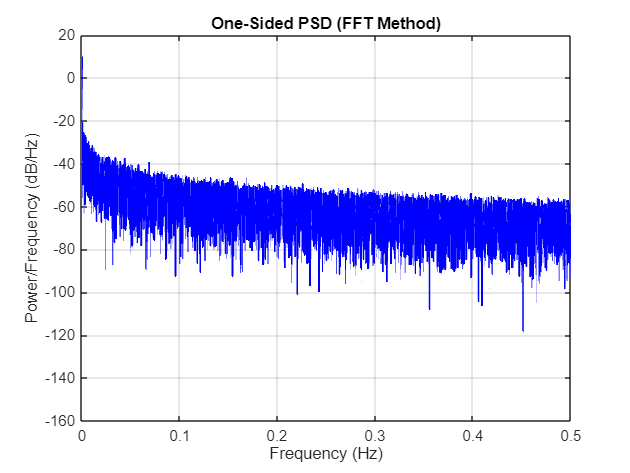


%% === Step 4: PSD using FFT ===
Fs = 10;             % Sampling frequency in Hz
N = length(wind_final);
Y = fft(wind_final);
P2 = abs(Y/N).^2;
P1 = P2(1:floor(N/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
f_fft = Fs*(0:floor(N/2))/N;  % Linear frequency in Hz
P1_dB = 10*log10(P1);

figure;
plot(f_fft, P1_dB, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('One-Sided PSD (FFT Method)');
xlim([0 0.5]);
ylim([-160 20]);

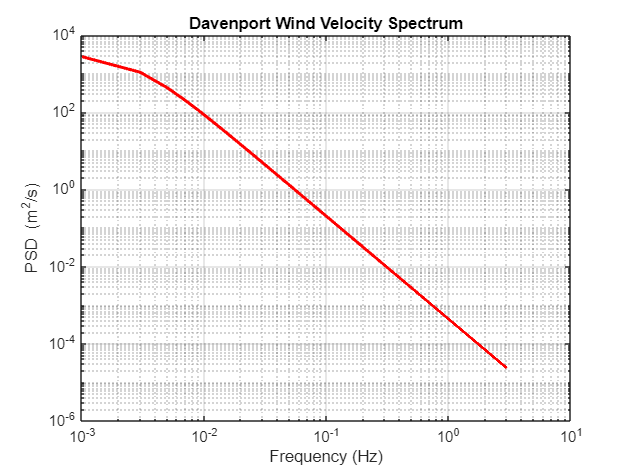


%% === Step 5: Davenport Spectrum (Theoretical) ===
U = mean_clean;      % Mean wind speed from cleaned data
z = 23.16;           % Antenna height (m)
z0 = 0.03;           % Roughness length (m)
b = 600 / (pi * U);
k = (1 / (2.5 * log(z/z0)))^2;

% Frequency range and Davenport formula
f_theory = linspace(0.001, 3, 1500);
w_theory = 2 * pi * f_theory;
Sv = (4800 * U * b * k) ./ ((1 + (b^2) * w_theory.^2).^(4/3));
Sv_dB = 10*log10(Sv);

figure;
loglog(f_theory, Sv, 'r', 'LineWidth', 2);
grid on;
xlabel('Frequency (Hz)');
ylabel('PSD (m^2/s)');
title('Davenport Wind Velocity Spectrum');

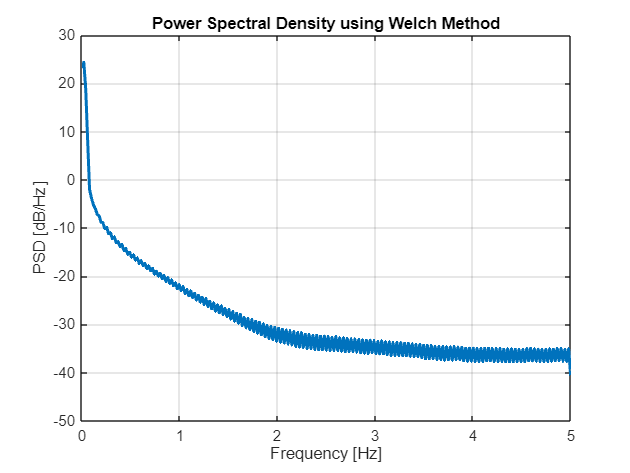


%% === Step 6: PSD using Welch ===
window = hamming(256);
noverlap = 128;
nfft = 512;
[pxx, f_welch] = pwelch(wind_final, window, noverlap, nfft, Fs);
pxx_dB = 10*log10(pxx);

figure;
plot(f_welch, pxx_dB, 'LineWidth', 2);
grid on;
xlabel('Frequency [Hz]');
ylabel('PSD [dB/Hz]');
title('Power Spectral Density using Welch Method');

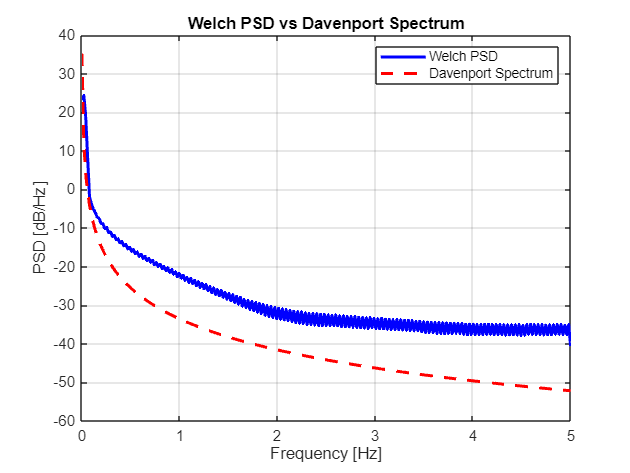


%% === Step 7: Compare Welch PSD with Davenport ===
w_welch = 2 * pi * f_welch;
Sv_welch = (4800 * U * b * k) ./ ((1 + (b^2) * w_welch.^2).^(4/3));
Sv_welch_dB = 10*log10(Sv_welch);

figure;
plot(f_welch, pxx_dB, 'b', 'LineWidth', 2); hold on;
plot(f_welch, Sv_welch_dB, 'r--', 'LineWidth', 2);
xlabel('Frequency [Hz]');
ylabel('PSD [dB/Hz]');
title('Welch PSD vs Davenport Spectrum');
legend('Welch PSD','Davenport Spectrum');
grid on;

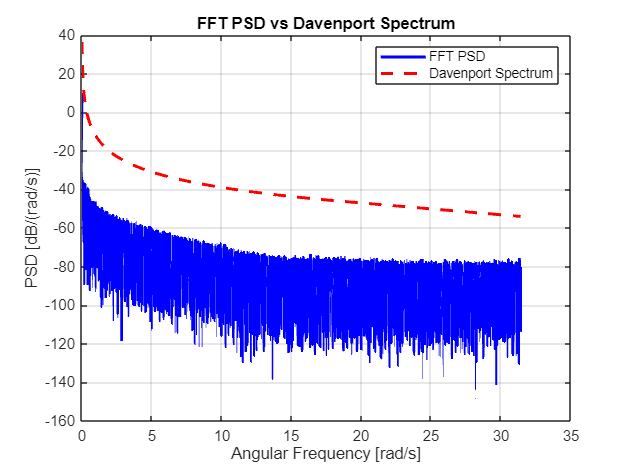


%% === Step 8: Compare FFT PSD with Davenport (Angular Frequency) ===
w_fft = 2 * pi * f_fft;
Sv_interp = interp1(w_theory, Sv_dB, w_fft, 'linear', 'extrap');

figure;
plot(w_fft, P1_dB, 'b', 'LineWidth', 2); hold on;
plot(w_fft, Sv_interp, 'r--', 'LineWidth', 2);
xlabel('Angular Frequency [rad/s]');
ylabel('PSD [dB/(rad/s)]');
title('FFT PSD vs Davenport Spectrum');
legend('FFT PSD','Davenport Spectrum');
grid on;